## **Name : Phuriwat Angkoondittaphong**

## Student ID : 6388003

## Section : 1

# **Triangulation Matting Project **

Read all 4 images

cg1 = imread("fg1.png");
bg1 = imread("bg1.png");
cg2 = imread("fg2.png");
bg2 = imread("bg2.png");

Display all 4 images

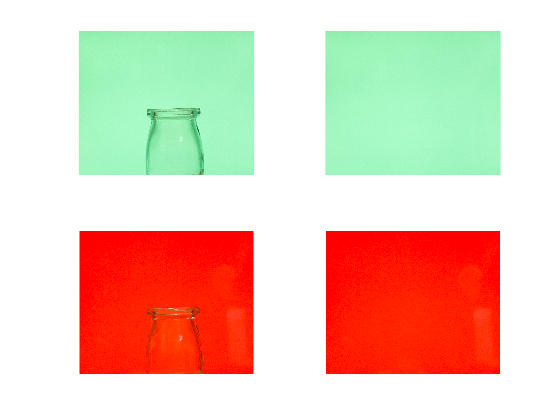

figure(1)
subplot(2, 2, 1); imshow(cg1)
subplot(2, 2, 2); imshow(bg1)
subplot(2, 2, 3); imshow(cg2)
subplot(2, 2, 4); imshow(bg2)

Convert to double

cg1 = im2double(cg1);
bg1 = im2double(bg1);
cg2 = im2double(cg2);
bg2 = im2double(bg2);

Compute alpha

cg1r = cg1(:, :, 1);
cg1g = cg1(:, :, 2);
cg1b = cg1(:, :, 3);
bg1r = bg1(:, :, 1);
bg1g = bg1(:, :, 2);
bg1b = bg1(:, :, 3);
cg2r = cg2(:, :, 1);
cg2g = cg2(:, :, 2);
cg2b = cg2(:, :, 3);
bg2r = bg2(:, :, 1);
bg2g = bg2(:, :, 2);
bg2b = bg2(:, :, 3);

alpha = 1 - ((cg1r - cg2r).*(bg1r - bg2r) + (cg1g - cg2g).*(bg1g - bg2g) + (cg1b - cg2b).*(bg1b - bg2b))./(power((bg1r - bg2r), 2) + power((bg1g - bg2g), 2) + power((bg1b - bg2b), 2));

Compute foreground colors of object from background 1 

fg1r = (cg1r - (1 - alpha).*bg1r) ./ alpha;
fg1g = (cg1g - (1 - alpha).*bg1g) ./ alpha;
fg1b = (cg1b - (1 - alpha).*bg1b) ./ alpha;

Compute foreground colors of object from background 2

fg2r = (cg2r - (1 - alpha).*bg2r) ./ alpha;
fg2g = (cg2g - (1 - alpha).*bg2g) ./ alpha;
fg2b = (cg2b - (1 - alpha).*bg2b) ./ alpha;

Display the extracted foreground object / matte from background 1 and 2

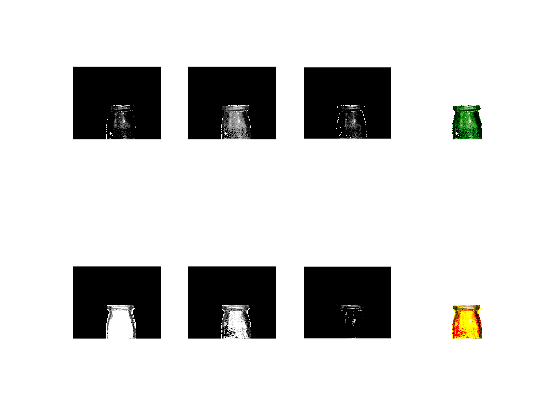

fg1 = zeros(720, 876, 3);
fg1(:, :, 1) = fg1r;
fg1(:, :, 2) = fg1g;
fg1(:, :, 3) = fg1b;
fg1(isnan(fg1)) = 1.;

fg2 = zeros(720, 876, 3);
fg2(:, :, 1) = fg2r;
fg2(:, :, 2) = fg2g;
fg2(:, :, 3) = fg2b;
fg2(isnan(fg2)) = 1.;

figure(2)
subplot(2, 4, 1); imshow(fg1r)
subplot(2, 4, 2); imshow(fg1g)
subplot(2, 4, 3); imshow(fg1b)
subplot(2, 4, 4); imshow(fg1)

subplot(2, 4, 5); imshow(fg2r)
subplot(2, 4, 6); imshow(fg2g)
subplot(2, 4, 7); imshow(fg2b)
subplot(2, 4, 8); imshow(fg2)

Perform the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

white_bg = ones(size(alpha));
white_img1 = alpha .* fg1 + (1 - alpha) .* white_bg;
white_img2 = alpha .* fg2 + (1 - alpha) .* white_bg;

Display the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

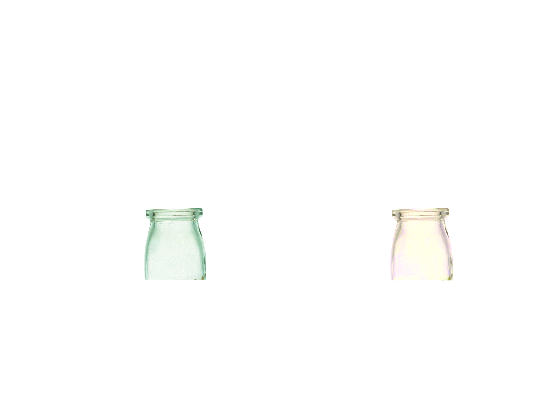

figure(3)
subplot(1, 2, 1); imshow(white_img1)
subplot(1, 2, 2); imshow(white_img2)

Read new background image to do the composition and display it.

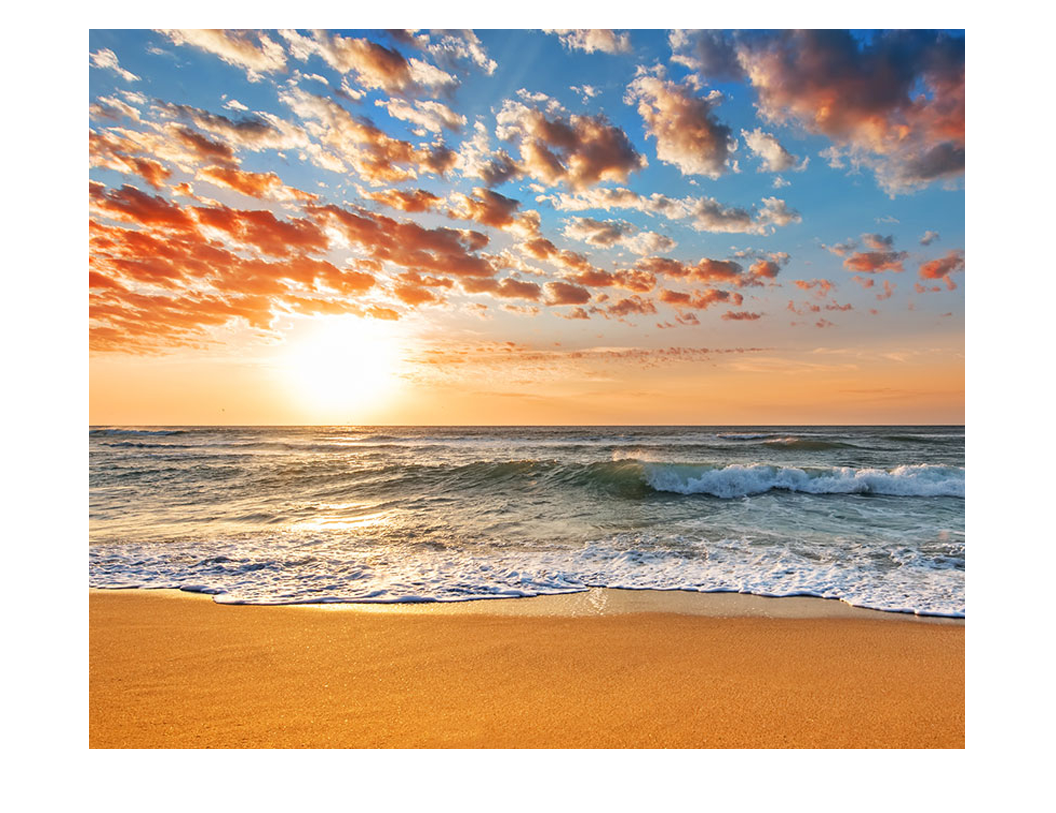

newbg = imread("new_bg1.png");
newbg = im2double(newbg);
figure(4)
imshow(newbg)

Perform the composition of extracted foreground object from background 1 and 2 with the new background image

newbg1 = alpha .* fg1 + (1 - alpha) .* newbg;
newbg2 = alpha .* fg2 + (1 - alpha) .* newbg;

Display the composition of extracted foreground object from background 1 and 2 with the new background image

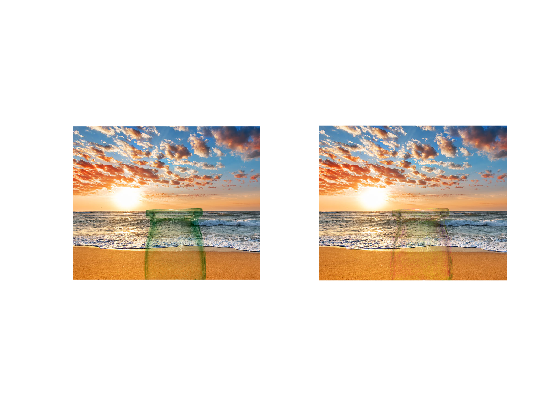

figure(5)
subplot(1, 2, 1); imshow(newbg1)
subplot(1, 2, 2); imshow(newbg2)